# MATLAB Optimization Project

Traveling Salesman problem 10 cities

%clc;close; clear;

figure(1)
Cities=[6.6, 7.1; 0.4, 0.3; 8.5, 2.8; 9.3, 0.5; 6.8, 1.0; 7.6, 8.2; 7.4, 6.9; 3.9, 3.4; 6.6, 9.5; 1.7, 0.3]

Cities =     6.6000    7.1000
    0.4000    0.3000
    8.5000    2.8000
    9.3000    0.5000
    6.8000    1.0000
    7.6000    8.2000
    7.4000    6.9000
    3.9000    3.4000
    6.6000    9.5000
    1.7000    0.3000


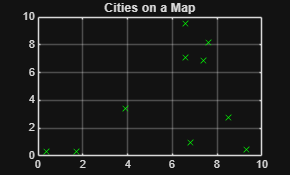

plot(Cities(:,1),Cities(:,2), 'xg')
xlim([0,10])
ylim([0,10])
grid on
title('Cities on a Map')

2 City test

function ds = EOMs(~,s,r)
    % s=[x, y, v, theta, LamX, LamY, LamV, LamTheta
    
    a = -r*s(7)/2;
    if abs(a)>1
        a=sign(a);
    end
    
    gamma = -r*s(8)/2;
    if abs(gamma)>1
        gamma=sign(gamma);
    end
   %state derrivitives 
    ds(1,1) = s(3)*cos(s(4)); % x_dot
    ds(2,1) = s(3)*sin(s(4)); % y_dot
    ds(3,1) = a; %v_dot
    ds(4,1) = gamma; %theta_dot

   %Costate derrivitives
    ds(5,1) = 0; %LamX_dot
    ds(6,1) = 0; %Lamy_dot
    ds(7,1) = -( s(5) * cos(s(4)) + s(6) * sin(s(4)) ); %LamV_dot
    ds(8,1) = -( s(3) * (-1 * s(5) * sin(s(4)) + s(6) * cos(s(4))) ); %LamTheta_dot
end

All Hail the Homotopy Constant:

r = 2;
fprintf('Homotopy Constant: %d', r);

Homotopy Constant: 2

theta_0 = 215;
guess =  [10, 10, 0, deg2rad(theta_0), 0.1 , 0.1 , -.8  , 0] 

guess =    10.0000   10.0000         0    3.7525    0.1000    0.1000   -0.8000         0


%initial:[x , y , v, heading         , lamX, LamY, LamV, LamTheta]

figure(2)
plot(Cities(:,1),Cities(:,2), 'xg') %plotting the origional cities
hold on
[T1, S1] = ode45( @(t,s)EOMs(t,s,r) , 0:0.1:2.4 , guess);
plot(S1(:,1),S1(:,2), '-y')


[T2, S2] = ode45( @(t,s)EOMs(t,s,r) , 2.4:0.1:3 , [S1(end,1:4), -2, -4, S1(end,7:8)]);
plot(S2(:,1),S2(:,2),'-r')

Taking Guess and ***Optimizing*** it.

solinit.x = linspace(0,1,11);
arc1 = interp1( T1/T1(end) , S1 , solinit.x );
arc2 = interp1( (T2-T1(end)) / (T2(end)-T1(end)) , S2 , solinit.x);

solinit.y = [arc1, arc2]'; %transpose the concatination of arc1 and arc2
fprintf('Size of Solinit.y is a: [%d, %d] matrix', size(solinit.y) )

Size of Solinit.y is a: [16, 11] matrix

solinit.parameters = [T1(end), T2(end)-T1(end)];

function ds = ELEOMs(t,s,p,r)
    ds(1:8,  1) = EOMs(t, s(1:8), r) * p(1);
    ds(9:16, 1) = EOMs(t, s(9:16), r) * p(2);
end

function constraint = bcfunc(si, sf, ~, r, Cities)
    %initial time (departure from depot)
    constraint(1,1) = si(1) - 10;
    constraint(2,1) = si(2) - 10;
    constraint(3,1) = si(3);
    constraint(4,1) = si(8);

    %intermediate time (arrival at city 1)
    constraint(5,1) = sf(1) - Cities(6,1); %x position of city 1
    constraint(6,1) = sf(2) - Cities(6,2); %y position of city 1
    constraint(7:10,1) = sf(1:4)-si(9:12); % x, y, v, & theta are continuous through intermediate time 
    constraint(11:12,1) = sf(7:8) - si(15:16); %only velocity and heading are unknown so costates are not 0 at intermediate time 
    a1 = max(-1, min(1, -r*sf(7)/2));
    gamma1 = max(-1, min(1, -r*sf(8)/2));
    
    constraint(13,1) = 1 + (1/r)*(a1^2+gamma1^2) + sf(5)*sf(3)*cos(sf(4)) + sf(6)*sf(3)*sin(sf(4))+ sf(7)*a1 + sf(8)*gamma1; %transversality condition (input H as its = 0) 
    
    %final time (arrival at city 2)
    constraint(14,1) = sf(9) - Cities(7,1); %x position of city 2
    constraint(15,1) = sf(10) - Cities(7,2); %y position of city 2
    constraint(16,1) = sf(15); %lamV active because velocity through city 2 is unknown
    constraint(17,1) = sf(16); %LamTheta active because heading through city 2 is unknown 
    a2 = max(-1, min(1, -r*sf(15)/2));
    gamma2 = max(-1, min(1, -r*sf(16)/2));
    
    constraint(18,1) = 1 + (1/r)*(a2^2+gamma2^2) + sf(13)*sf(11)*cos(sf(12)) + sf(14)*sf(11)*sin(sf(12)) + sf(15)*a2 + sf(16)*gamma2;
end

sol = bvp4c( @(t,s,p)ELEOMs(t, s, p, r), @(si, sf, p)bcfunc(si, sf, p, r, Cities), solinit);

fprintf('Soluition Converged! \nArc durration: %.4f, and %.4f seconds \nTotal time: %.4f', sol.parameters(1), sol.parameters(2), sum(sol.parameters(:,1)) );

Soluition Converged! 
Arc durration: 2.6455, and 0.6581 seconds 
Total time: 3.3036

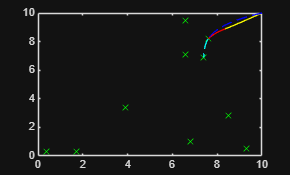


plot(sol.y(1,:),sol.y(2,:), '--b')
plot(sol.y(9,:),sol.y(10,:), '--c')